# Parallel derivative performance analysis

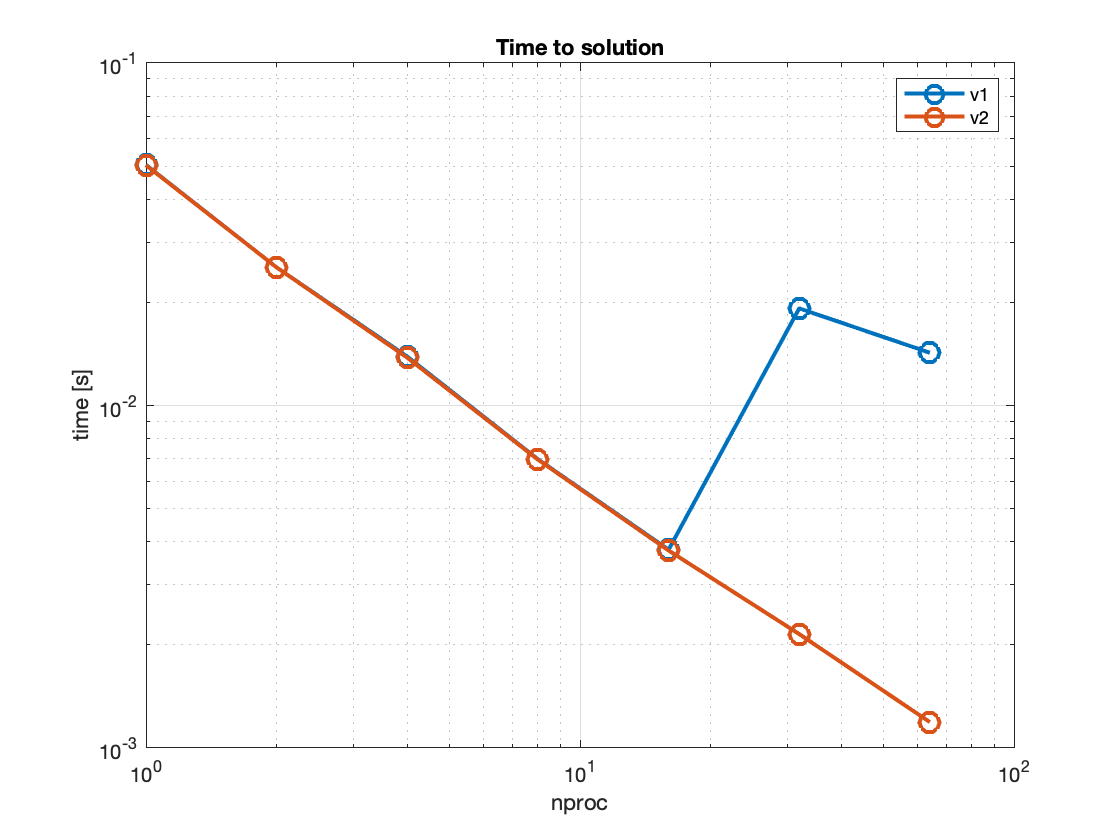

clear all;
clf;

data_file1 = 'dudx.o312354';

font_size = 14;

%[pp,nn,t1] = importfile(data_file1,1, nruns*ndsize);
%[pp,nn,t2] = importfile(data_file2,1, nruns*ndsize);

[nproc, npts, time_v1, error_v1, time_v2, error_v2, time_v3, error_v3] = importfile(data_file1);
loglog(nproc,time_v1,'-o',nproc,time_v2,'-o','LineWidth',2,'MarkerSize',10);
grid on;
legend('v1', 'v2')
xlabel('nproc'); ylabel('time [s]')
title('Time to solution');

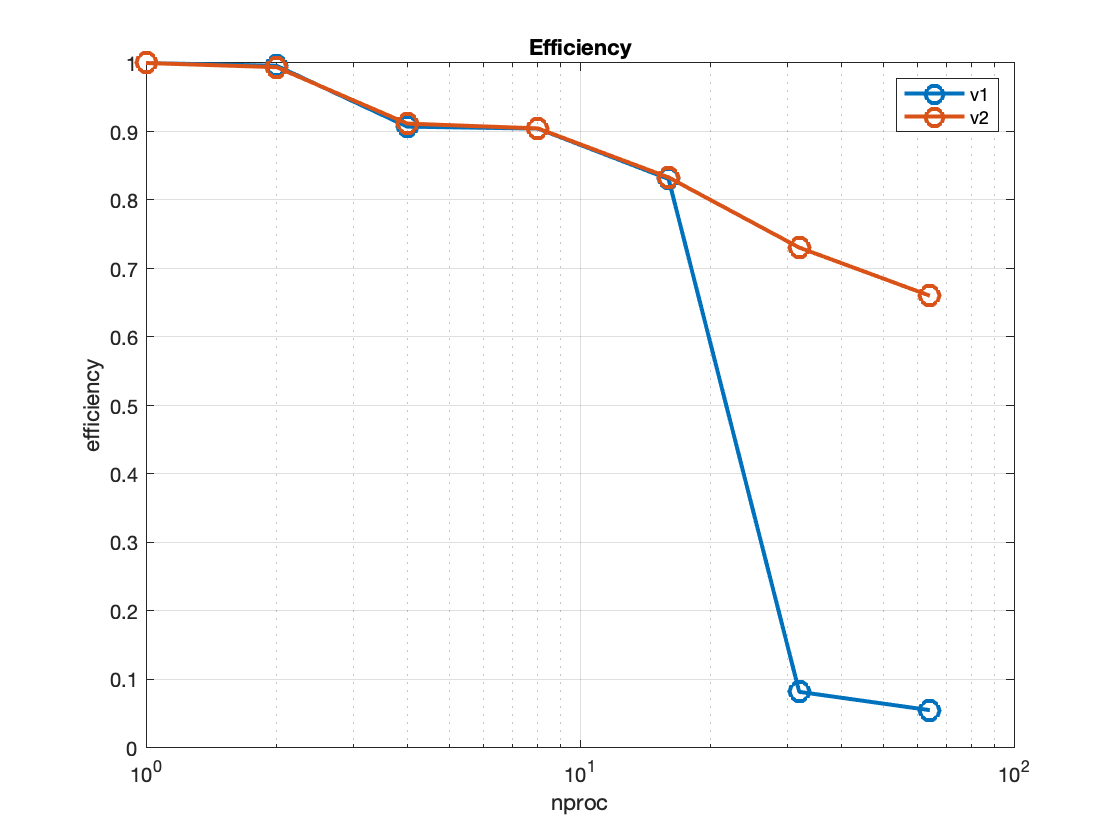

efficiency_v1 = time_v1(1)./time_v1./nproc;
efficiency_v2 = time_v2(1)./time_v2./nproc;
semilogx(nproc,efficiency_v1,'-o',nproc,efficiency_v2,'-o','LineWidth',2,'MarkerSize',10);
grid on;
legend('v1', 'v2')
xlabel('nproc'); ylabel('efficiency')
title('Efficiency');

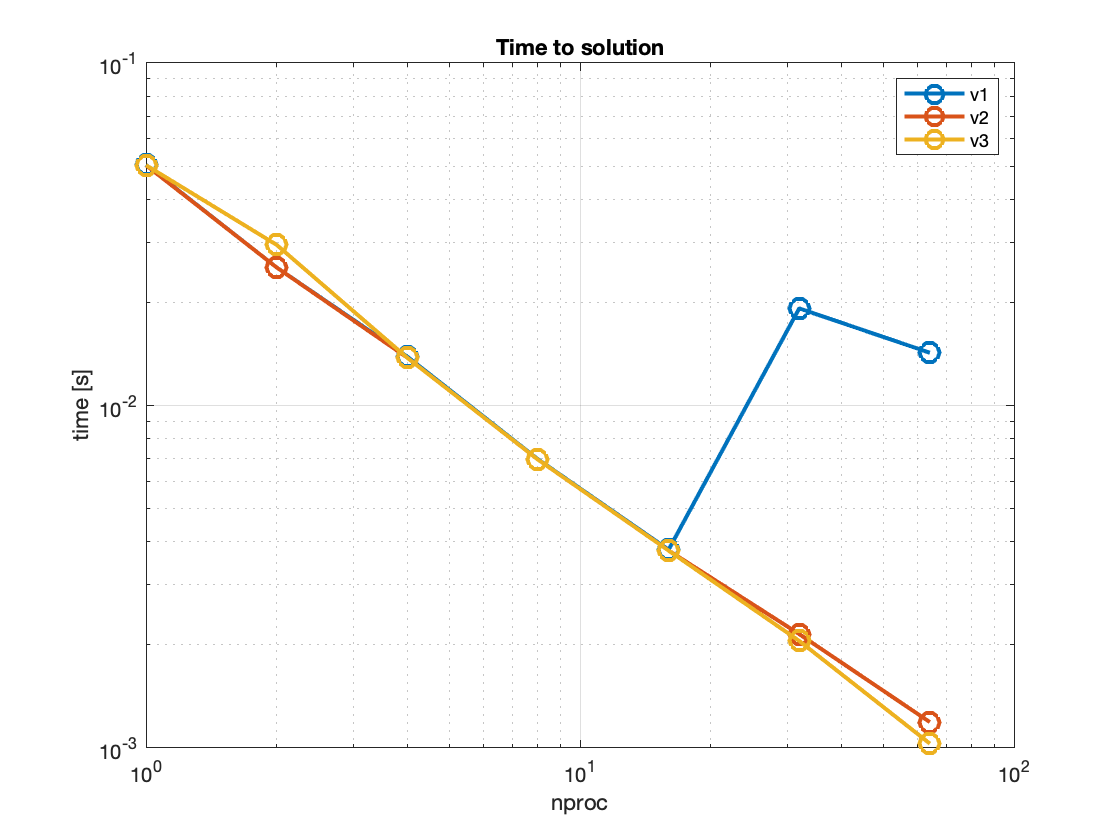


loglog(nproc,time_v1,'-o',nproc,time_v2,'-o',nproc,time_v3,'-o','LineWidth',2,'MarkerSize',10);
grid on;
legend('v1', 'v2', 'v3')
xlabel('nproc'); ylabel('time [s]')
title('Time to solution');

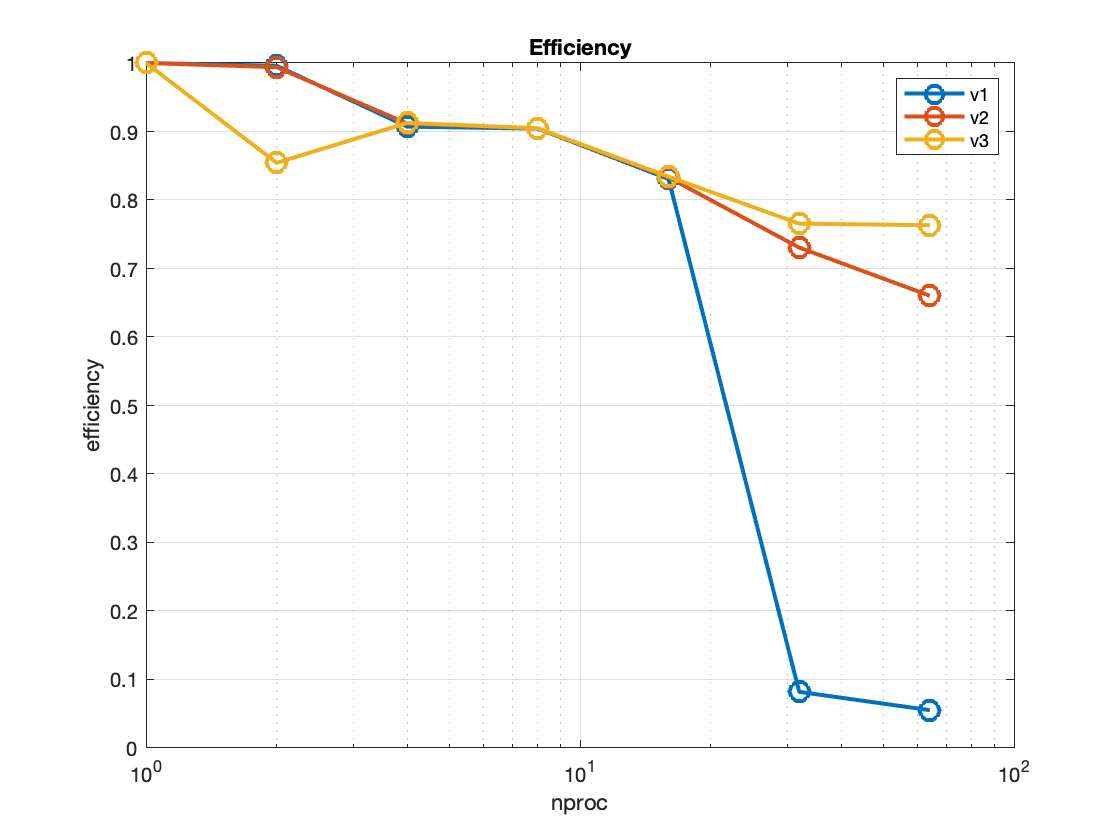

efficiency_v1 = time_v1(1)./time_v1./nproc;
efficiency_v2 = time_v2(1)./time_v2./nproc;
efficiency_v3 = time_v3(1)./time_v3./nproc;
semilogx(nproc,efficiency_v1,'-o',nproc,efficiency_v2,'-o',nproc,efficiency_v3,'-o','LineWidth',2,'MarkerSize',10);
grid on;
legend('v1', 'v2', 'v3')
xlabel('nproc'); ylabel('efficiency')
title('Efficiency');